**Assignment 1**

Load data

clear
load points2D_Set1.mat
scatter(x,y)
hold on

PCA

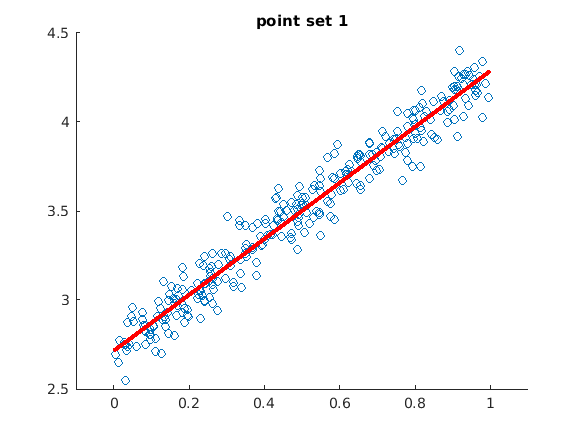

mx = sum(x)/300;
my = sum(y)/300;
x = x-mx;
y = y-my;
c = [x'*x , x'*y ; x'*y , y'*y] / size(x);
[u, ~] = svd(c);
pl = linspace(-mx,1-mx,100)/u(1,1);
line(u(1,1) .* pl' + mx, u(2,1) .* pl' + my,'LineWidth',3,'Color','red' );
xlim([-0.1 1.1]);
title("point set 1");
hold off

Point set 2

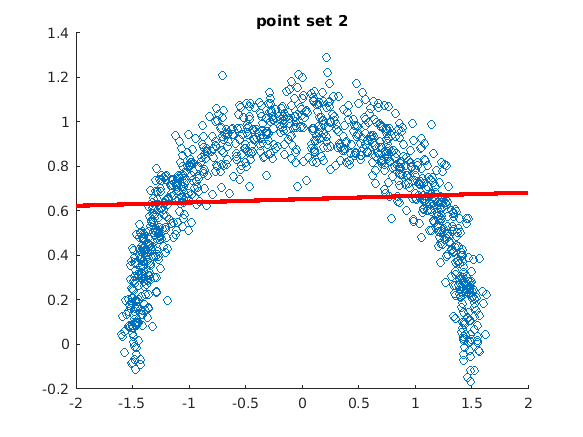

clear
load points2D_Set2.mat
scatter(x,y)
hold on
mx = sum(x) / 1000;
my = sum(y) / 1000;
x = x-mx;
y = y-my;
c = [x'*x , x'*y ; x'*y , y'*y] / size(x);
[u, ~ ] = svd(c);
pl = linspace(-2-mx,2-mx,100)/u(1,1);
line(u(1,1) .* pl' + mx, u(2,1) .* pl' + my,'LineWidth',3,'Color','red' );
title("point set 2");
hold off;